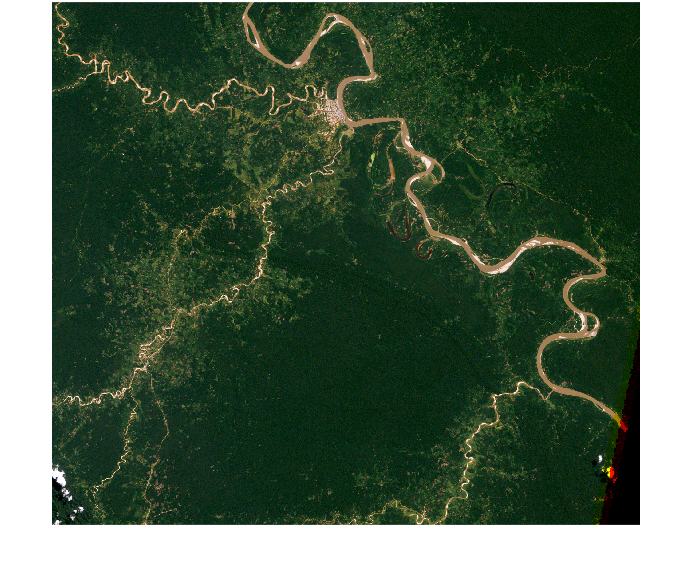

clear;
M = 1701; N = 1913;
image = zeros(2, M, N, 3);
image(1,:,:,:) = imread("imageSeries2_year2001.png");
image(2,:,:,:) = imread("imageSeries2_year2019.png");
image = uint8(image);
imshow(squeeze(image(1,:,:,:)))

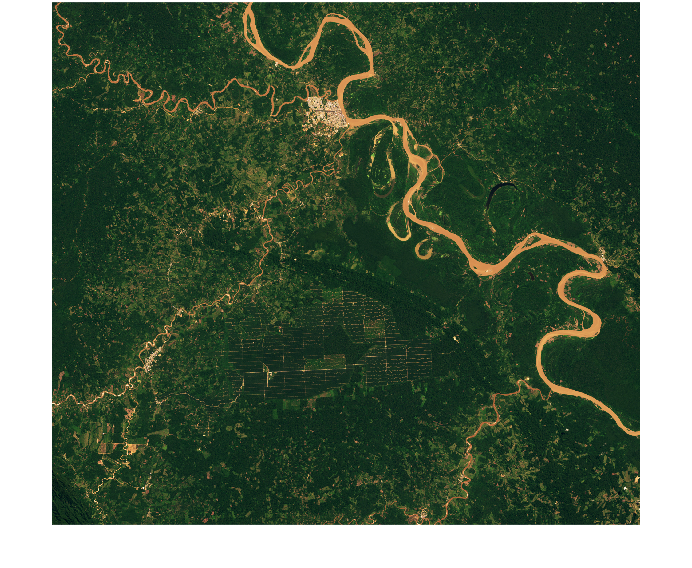

imshow(squeeze(image(2,:,:,:)))

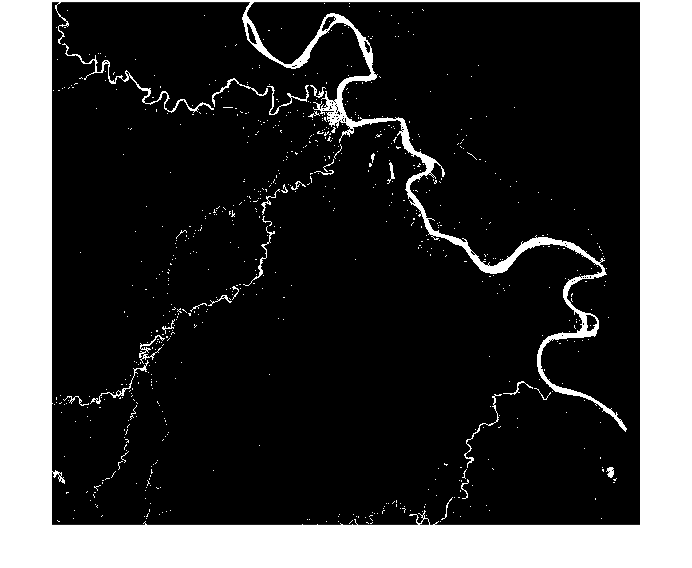


%thresholds specific to series of images (and goal)
%these thresholds for identifying river
rThresh = [0  .45];
gThresh = [0 1];
bThresh = [.6 1];

BW = zeros(2, M, N); %instantiate BW image array
BW(1, :, :) = getMask(squeeze(image(1,:,:,:)), rThresh, gThresh, bThresh);
BW(2, :, :) = getMask(squeeze(image(2,:,:,:)), rThresh, gThresh, bThresh);

imshow(squeeze(BW(1,:,:)))

imshow(squeeze(BW(2, :,:)))


%indices to set 0 (that are 1 in the BW)
idx = zeros(2, M, N);
idx(1, :, :) = BW(1,:,:)==1;
idx(2, :, :) = BW(2, :, :) == 1;
idx = logical(idx); 

%repeat mask so that you are only masking w/ respect to specific indices

%these thresholds for identifying deforested areas

rThresh = [0 .21]; 
gThresh=  [0 1];
bThresh = [ 0 .791];
BW(1, :, :) = getMask(squeeze(image(1,:,:,:)), rThresh, gThresh, bThresh);
BW(2, :, :) = getMask(squeeze(image(2,:,:,:)), rThresh, gThresh, bThresh);
imshow(squeeze(BW(1,:,:)))

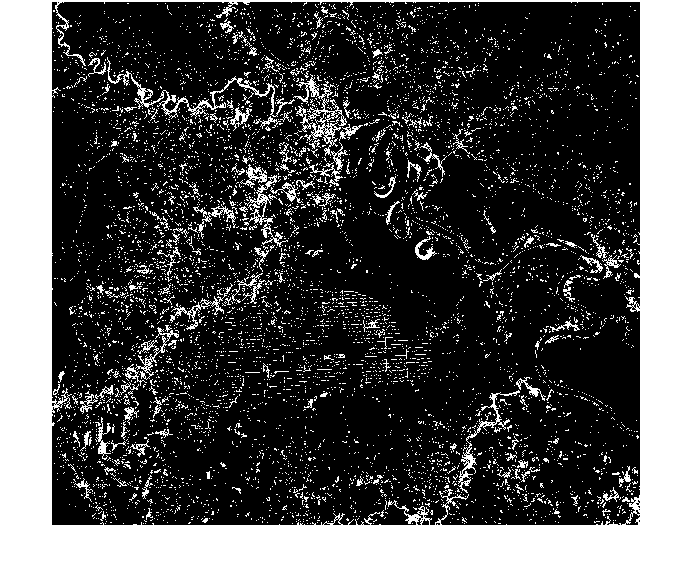

imshow(squeeze(BW(2,:,:)))

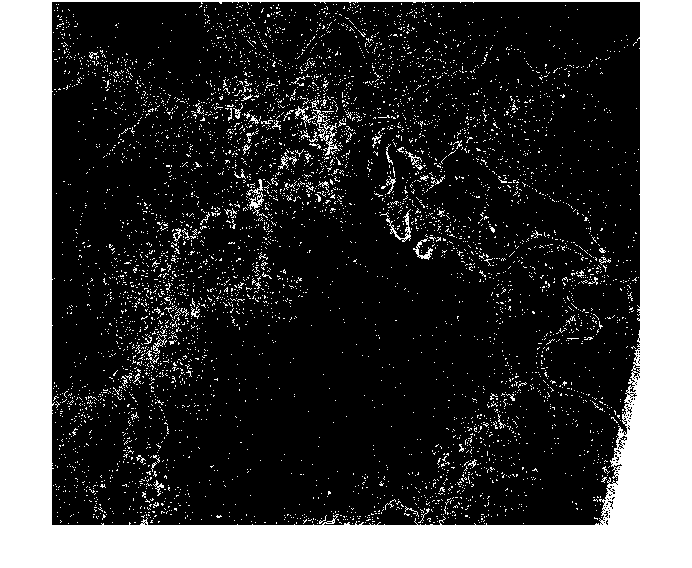



%change 1 values of prev mask to 0 (to ignore river)
BW(1,:,:) = setZero(squeeze(BW(1,:,:)), squeeze(idx(1,:,:)));
BW(2, :,:) = setZero(squeeze(BW(2,:,:)),squeeze(idx(2,:,:)));
imshow(squeeze(BW(1,:,:)))

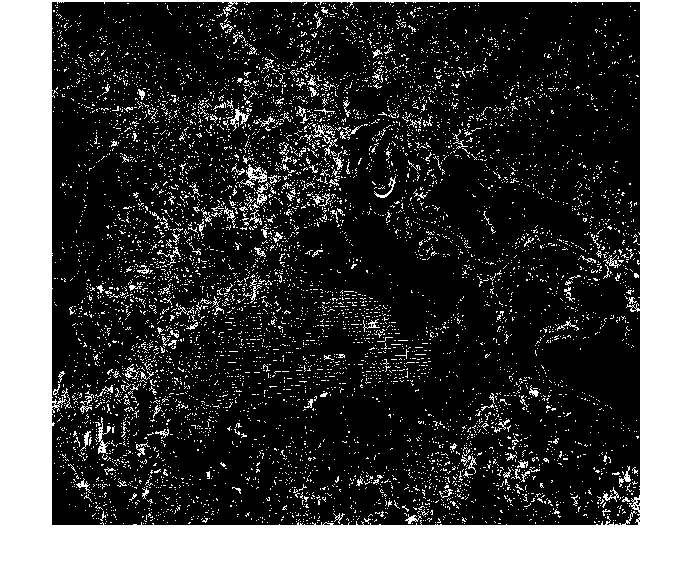

imshow(squeeze(BW(2,:,:)))

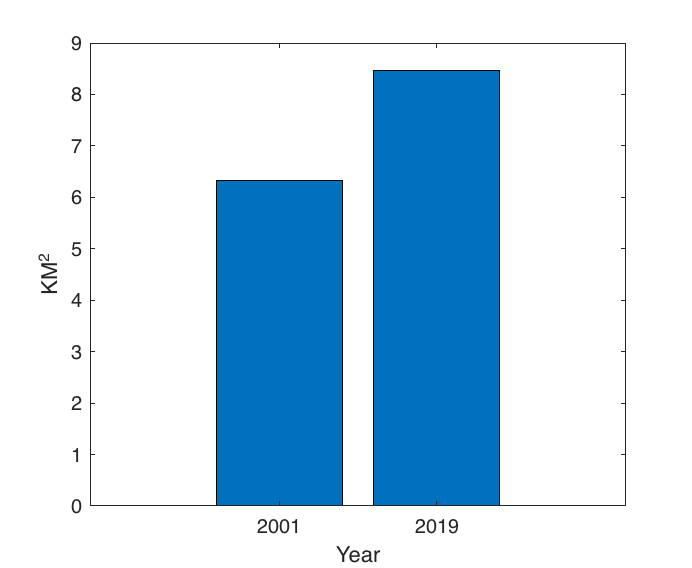




%get percent of deforestation

deforestPercent = zeros(1, 2);
%deforestArea = zeros(1, num);
numIgnore = nnz(idx(1,:,:)); %num of elements to ignore (elements that are 1 from river)
for i = 1:2
    currentRGBImage = squeeze(image(i,:,:,:));
    
    numWhite = nnz(BW(i,:,:));% # white pixels
    numTotal = numel(BW(i,:,:))-numIgnore; % # of total pixels, except those from first mask (river)

    deforestPercent(i) = numWhite / numTotal; %percent deforestation of each image
    %deforestArea(i) = deforestPercent(i) * area; %deforested area of each image
end

years = [2001, 2019];
deforestArea = deforestPercent .*100; %assume 100 km area image for now
bar(years, deforestArea);
ylabel('KM^2')
xlabel('Year')

function I = setZero(I, idx)
    Zeros = zeros(size(I));
    I(idx) = Zeros(idx);
end
